eeg1=datastrap.eeg1;
eeg2=datastrap.eeg2;
eeg3=datastrap.eeg3;
eeg4=datastrap.eeg4;

f=length(eeg1)/120;
t=1/f;

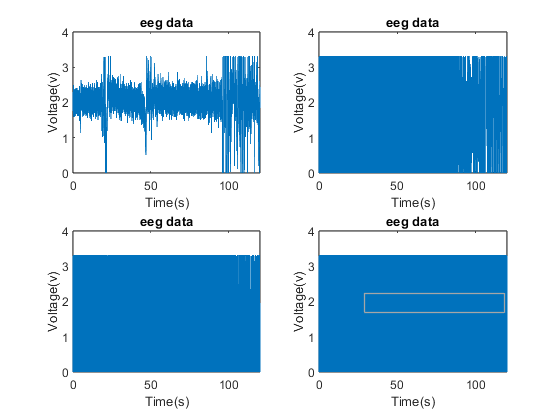

t_D=[0:1:length(eeg2)-1]*t;
figure;
subplot(2,2,1)
plot(t_D,eeg1)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

subplot(2,2,2)
plot(t_D,eeg2)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')
subplot(2,2,3)
plot(t_D,eeg3)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')
subplot(2,2,4)
plot(t_D,eeg4)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

eeg1_Fft=fft(eeg1);
eeg1_Fft(1)=0;
eeg1=ifft(eeg1_Fft);

eeg2_Fft=fft(eeg2);
eeg2_Fft(1)=0;
eeg2=ifft(eeg2_Fft);

eeg3_Fft=fft(eeg3);
eeg3_Fft(1)=0;
eeg3=ifft(eeg3_Fft);

eeg4_Fft=fft(eeg4);
eeg4_Fft(1)=0;
eeg4=ifft(eeg4_Fft);

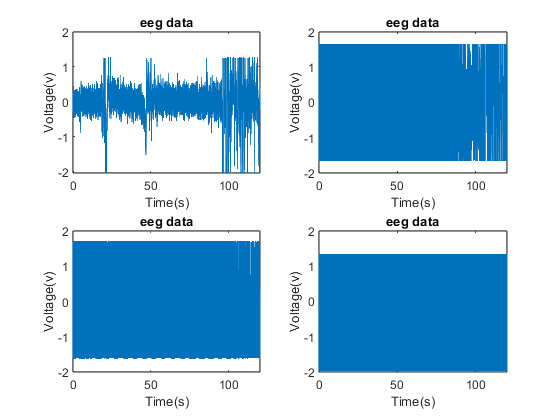

figure;
subplot(2,2,1)
plot(t_D,eeg1)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

subplot(2,2,2)
plot(t_D,eeg2)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')
subplot(2,2,3)
plot(t_D,eeg3)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')
subplot(2,2,4)
plot(t_D,eeg4)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

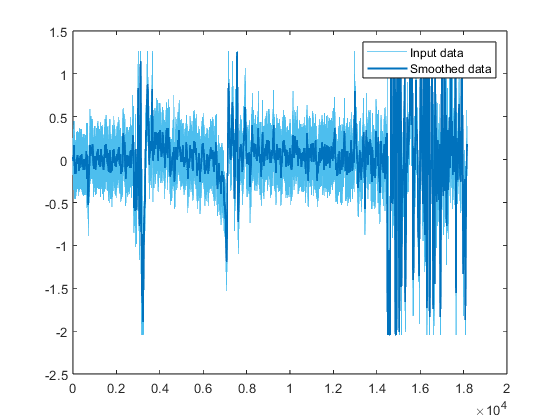

% Smooth input data
smoothedData1 = smoothdata(eeg1,"movmean",[9.5 9.5]);

% Display results
clf
plot(eeg1,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData1,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

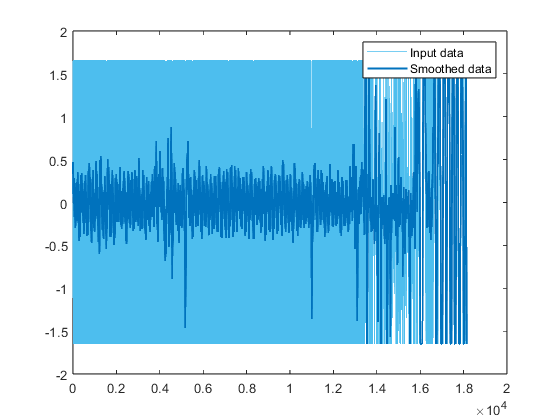

% Smooth input data
smoothedData2 = smoothdata(eeg2,"movmean",[9.5 9.5]);

% Display results
clf
plot(eeg2,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

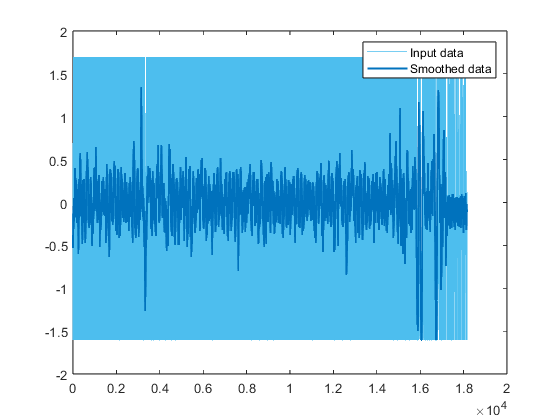

% Smooth input data
smoothedData3 = smoothdata(eeg3,"movmean",[9 9]);

% Display results
clf
plot(eeg3,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData3,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

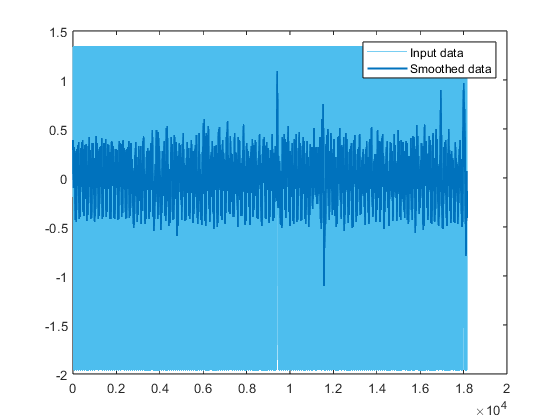

% Smooth input data
smoothedData4 = smoothdata(eeg4,"movmean",19);

% Display results
clf
plot(eeg4,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData4,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

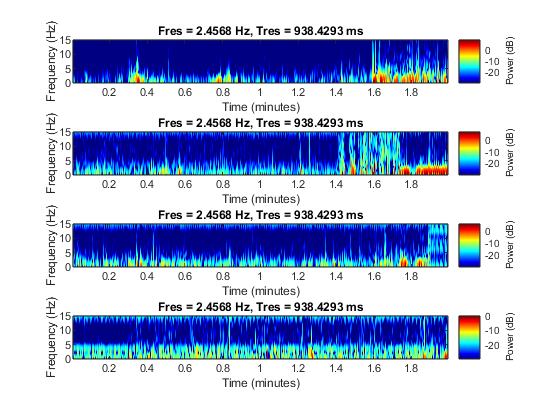

figure;
colormap jet;
subplot(4,1,1)
pspectrum(eeg1,f,"spectrogram","MinThreshold",-30,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)
subplot(4,1,2)
pspectrum(eeg2,f,"spectrogram","MinThreshold",-30,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)
subplot(4,1,3)
pspectrum(eeg3,f,"spectrogram","MinThreshold",-30,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)
subplot(4,1,4)
pspectrum(eeg4,f,"spectrogram","MinThreshold",-30,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

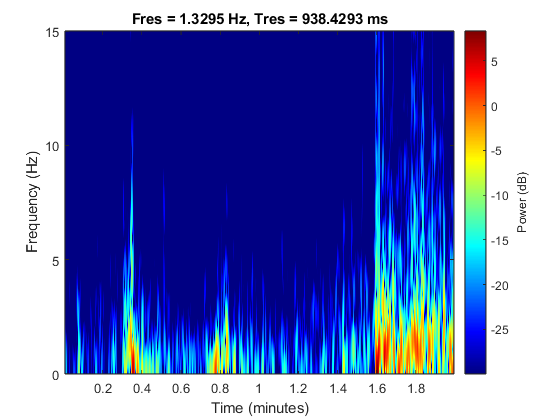

figure;
colormap jet;

pspectrum(eeg1,f,"spectrogram","MinThreshold",-30,"FrequencyLimits",[0,15],"Leakage",0.9,"OverlapPercent",90)

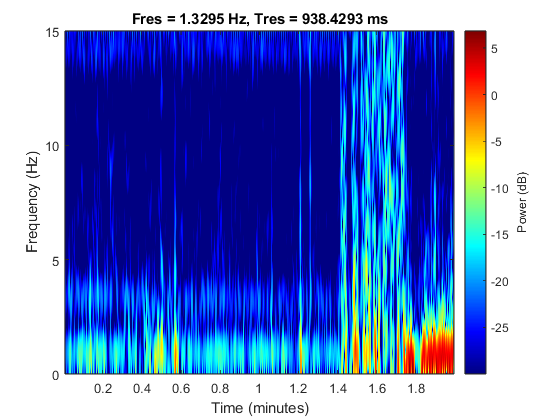


pspectrum(eeg2,f,"spectrogram","MinThreshold",-30,"FrequencyLimits",[0,15],"Leakage",0.9,"OverlapPercent",90)

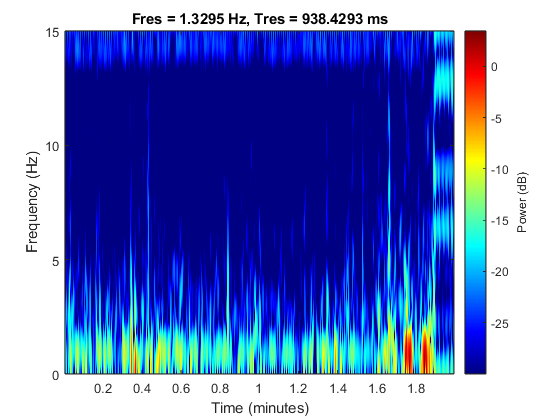


pspectrum(eeg3,f,"spectrogram","MinThreshold",-30,"FrequencyLimits",[0,15],"Leakage",0.9,"OverlapPercent",90)

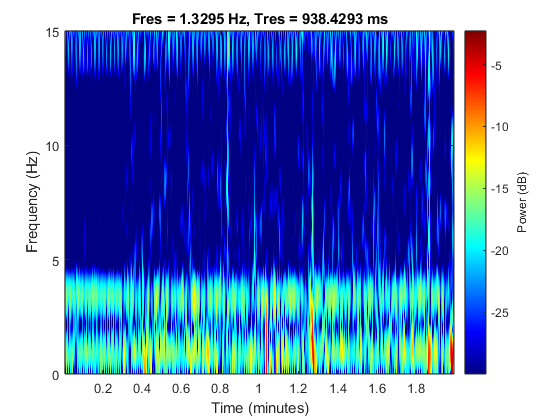


pspectrum(eeg4,f,"spectrogram","MinThreshold",-30,"FrequencyLimits",[0,15],"Leakage",0.9,"OverlapPercent",90)

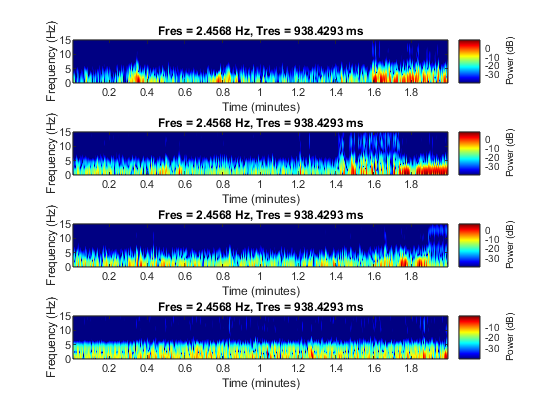

figure;
colormap jet;
subplot(4,1,1)
pspectrum(smoothedData1,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)
subplot(4,1,2)
pspectrum(smoothedData2,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)
subplot(4,1,3)
pspectrum(smoothedData3,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)
subplot(4,1,4)
pspectrum(smoothedData4,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.6,"OverlapPercent",90)

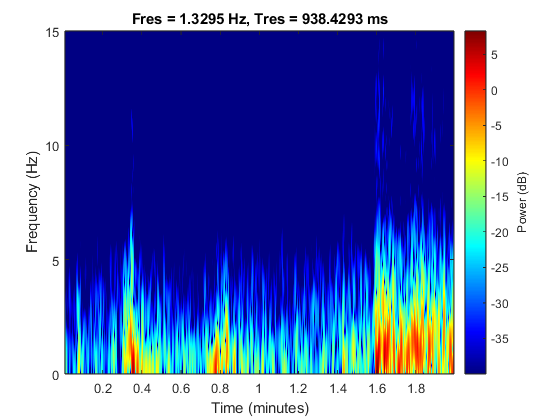

figure;
colormap jet;

pspectrum(smoothedData1,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.9,"OverlapPercent",90)

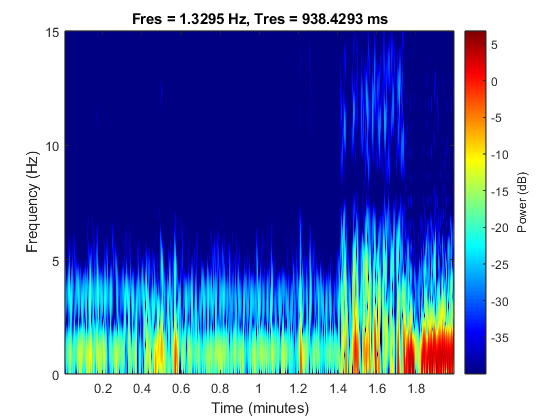


pspectrum(smoothedData2,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.9,"OverlapPercent",90)

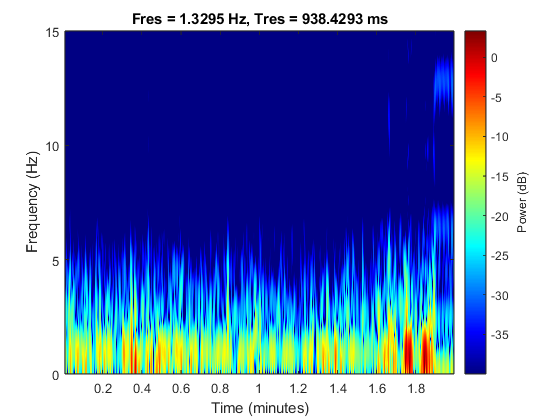


pspectrum(smoothedData3,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.9,"OverlapPercent",90)

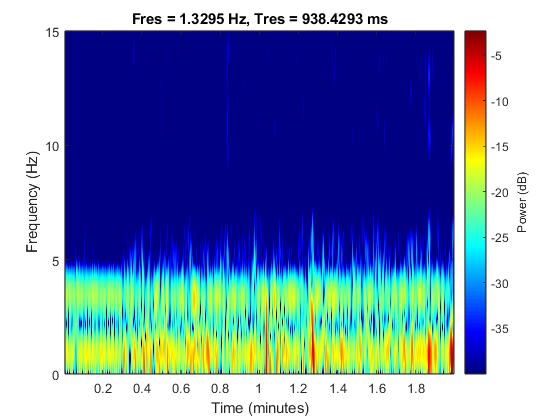


pspectrum(smoothedData4,f,"spectrogram","MinThreshold",-40,"FrequencyLimits",[0,15],"Leakage",0.9,"OverlapPercent",90)